clear
clc
close all
% --------------------------------------------------------------------------
data = importdata("magnets_data.txt");

gt_pos = data(:,1);
gt_vel = data(:,2);
gt_sensor = data(:,3);

% Partical Filter Variables
M = 1000; %number of particles
sig_a = 0.0625; % Variance of dynamic noise
sig_m = 4;
sig_n = 0.003906; % variance of measurement noise
Xm1 = -10; % position of magnet
Xm2 = 10;   % position of magnet
% CV = 0;
resample_ct = 1;

% Initialization of weights and state variables
x_pos = zeros(M,1);
x_vel = zeros(M,1);
x_pos_prev = zeros(M,1);
x_vel_prev = zeros(M,1);

wt_norm = 1/M * zeros(M,1);
wt_prev = 1/M * ones(M,1);
wt_up = 1/M * zeros(M,1);

index = zeros(M,1);
x_pos_1 = zeros(M,1);
x_vel_1 = zeros(M,1);
wt_norm_1 = zeros(M,1);

%plot flags
resampling_count = 0

resampling_count = 0

wt_plt = 0; %weight plots
resample_plt = 10; % resampling plots will start at this point

%resampling threshold
rs_thresh = 0.5 ;

X1 = 1:length(gt_sensor);
X2 = 1:M;

result = zeros(length(gt_sensor),1);


for i = 1:length(gt_sensor)
%     E(i) = 0;
      
    for j = 1:1:M
        x_pos(j) = x_pos_prev(j) + x_vel_prev(j);
        if(x_pos_prev(j) < -20)
            x_vel(i) = 2;
            
        elseif(x_pos_prev(j) >= -20 && x_pos_prev(j) < 0 )
            x_vel(j) = x_vel_prev(j) + abs(normrnd(0,sig_a));
            
        elseif(x_pos_prev(j) >= 0 && x_pos_prev(j) <= 20)
            x_vel(j) = x_vel_prev(j) - abs(normrnd(0,sig_a));
            
        elseif(x_pos_prev(j) > 20)
            x_vel(j) = -2;
        end
        
        y_t = ( (1/(sqrt(2*pi)*sig_m)) * exp((-(x_pos_prev(j)-Xm1)^2) / (2*sig_m^2)) ) + (1/(sqrt(2*pi)*sig_m)) * exp(-(x_pos_prev(j)-Xm2)^2 / (2 *(sig_m^2)) );
        
        %weight updates via ideal measurement
        p = (1/(sqrt(2*pi)*sig_n)) * exp (-(y_t-gt_sensor(i))^2 / (2 * sig_n^2)) ;
        
        wt_up(j) = wt_prev(j) *  p;        
        wt_prev(j) = wt_up(j);
        x_pos_prev(j) = x_pos(j);
        x_vel_prev(j) = x_vel(j);
    end
    %weight normalization
    wt_norm = wt_up ./ sum(wt_up);
%     sum(wt_up)
    E =0 ;
    for k = 1:M
        E = E + (wt_norm(k) * x_pos(k));
%         E(i) = E(i) + wt_norm(k) + x_pos(k);
    end
    
    result(i) = E;
    
    CV = 0;

    for k = 1:M
        CV = CV + (M*wt_norm(k) - 1)^2;
    end
    
    CV = CV/M;
    ESS = M/(1+CV);
    
    if(wt_plt==90)
        figure(i)
        bar(X2, wt_norm,'k')
        xlabel('No of Particles');
        ylabel('Weight');
        set(gca,'FontSize',24)
%         disp(strcat('iteration = ',num2str(t), ' ESS = ', num2str(ESS) ))
    end
    
    if ESS <rs_thresh*M
        
        resampling_count = resampling_count + 1
        if resampling_count == resample_plt
            wt_plt = 1;
        end
        
        Q = cumsum(wt_norm);
        t = rand(M+1,1);
        T = sort(t);
        T(M+1) = 1;
        x=1;
        y=1;
        while x<=M
           
            if T(x) < Q(y)
               index(x) = y;
               x = x+1;
           else
               y=y+1;
           end
        end
        for x = 1:M
            x_pos(x)      = x_pos(index(x));
            x_pos_prev(x)  = x_pos_prev(index(x));

            x_vel(x)        = x_vel(index(x));
            x_vel_prev(x)    = x_vel_prev(index(x)) ;

            wt_norm(x)          = 1/M;
            wt_prev(x)     = 1/M;
        end
%            for x=1:M
%                x_pos_1(x) = x_pos(index(x));
%                wt_norm_1(x) = 1/M;
%                x_vel_1(x) = x_vel(index(x));
%            end
%         x_pos = x_pos_1;
%         wt_norm = wt_norm_1;
%         x_vel = x_vel_1;
    end
%     wt_prev = wt_norm; % uncmnt this blokc it works
%     x_pos_prev = x_pos;
%     x_vel_prev = x_vel;
end

resampling_count = 1

resampling_count = 2

resampling_count = 3

resampling_count = 4

resampling_count = 5

resampling_count = 6

resampling_count = 7

resampling_count = 8

resampling_count = 9

resampling_count = 10

resampling_count = 11

resampling_count = 12

resampling_count = 13

resampling_count = 14

resampling_count = 15

resampling_count = 16

resampling_count = 17

resampling_count = 18

resampling_count = 19

resampling_count = 20

resampling_count = 21

resampling_count = 22

resampling_count = 23

resampling_count = 24

resampling_count = 25

resampling_count = 26

resampling_count = 27

resampling_count = 28

resampling_count = 29

resampling_count = 30

resampling_count = 31

resampling_count = 32

resampling_count = 33

resampling_count = 34

resampling_count = 35

resampling_count = 36

resampling_count = 37

resampling_count = 38

resampling_count = 39

resampling_count = 40

resampling_count = 41

resampling_count = 42

resampling_count = 43

resampling_count = 44

resampling_count = 45

resampling_count = 46

resampling_count = 47

resampling_count = 48

resampling_count = 49

resampling_count = 50

resampling_count = 51

resampling_count = 52

resampling_count = 53

resampling_count = 54

resampling_count = 55

resampling_count = 56

resampling_count = 57

resampling_count = 58

resampling_count = 59

resampling_count = 60

resampling_count = 61

resampling_count = 62

resampling_count = 63

resampling_count = 64

resampling_count = 65

resampling_count = 66

resampling_count = 67

resampling_count = 68

resampling_count = 69

resampling_count = 70

resampling_count = 71

resampling_count = 72

resampling_count = 73

resampling_count = 74

resampling_count = 75

resampling_count = 76

resampling_count = 77

resampling_count = 78

resampling_count = 79

resampling_count = 80

resampling_count = 81

resampling_count = 82

resampling_count = 83

resampling_count = 84

resampling_count = 85

resampling_count = 86

resampling_count = 87

resampling_count = 88

resampling_count = 89

resampling_count = 90

resampling_count = 91

resampling_count = 92

resampling_count = 93

resampling_count = 94

resampling_count = 95

resampling_count = 96

resampling_count = 97

resampling_count = 98

resampling_count = 99

resampling_count = 100

resampling_count = 101

resampling_count = 102

resampling_count = 103

resampling_count = 104

resampling_count = 105

resampling_count = 106

resampling_count = 107

resampling_count = 108

resampling_count = 109

resampling_count = 110

resampling_count = 111

resampling_count = 112

resampling_count = 113

resampling_count = 114

resampling_count = 115

resampling_count = 116

resampling_count = 117

resampling_count = 118

resampling_count = 119

resampling_count = 120

resampling_count = 121

resampling_count = 122

resampling_count = 123

resampling_count = 124

resampling_count = 125

resampling_count = 126

resampling_count = 127

resampling_count = 128

resampling_count = 129

resampling_count = 130

resampling_count = 131

resampling_count = 132

resampling_count = 133

resampling_count = 134

resampling_count = 135

resampling_count = 136

resampling_count = 137

resampling_count = 138

resampling_count = 139

resampling_count = 140

resampling_count = 141

resampling_count = 142

resampling_count = 143

resampling_count = 144

resampling_count = 145

resampling_count = 146

resampling_count = 147

resampling_count = 148

resampling_count = 149

resampling_count = 150

resampling_count = 151

resampling_count = 152

resampling_count = 153

resampling_count = 154

resampling_count = 155

resampling_count = 156

resampling_count = 157

resampling_count = 158

resampling_count = 159

resampling_count = 160

resampling_count = 161

resampling_count = 162

resampling_count = 163

resampling_count = 164

resampling_count = 165

resampling_count = 166

resampling_count = 167

resampling_count = 168

resampling_count = 169

resampling_count = 170

resampling_count = 171

resampling_count = 172

resampling_count = 173

resampling_count = 174

resampling_count = 175

resampling_count = 176

resampling_count = 177

resampling_count = 178

resampling_count = 179

resampling_count = 180

resampling_count = 181

resampling_count = 182

resampling_count = 183

resampling_count = 184

resampling_count = 185

resampling_count = 186

resampling_count = 187

resampling_count = 188

resampling_count = 189

resampling_count = 190

resampling_count = 191

resampling_count = 192

resampling_count = 193

resampling_count = 194

resampling_count = 195

resampling_count = 196

resampling_count = 197

resampling_count = 198

resampling_count = 199

resampling_count = 200

resampling_count = 201

resampling_count = 202

resampling_count = 203

resampling_count = 204

resampling_count = 205

resampling_count = 206

resampling_count = 207

resampling_count = 208

resampling_count = 209

resampling_count = 210

resampling_count = 211

resampling_count = 212

resampling_count = 213

resampling_count = 214

resampling_count = 215

resampling_count = 216

resampling_count = 217

resampling_count = 218

resampling_count = 219

resampling_count = 220

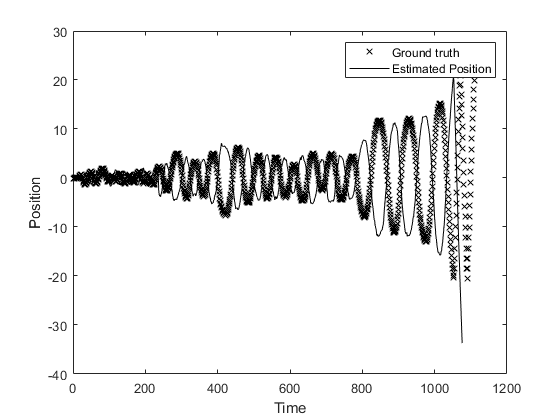

plot(gt_pos,"kx")
hold on
plot(result,"k-")
xlabel("Time")
ylabel("Position")
legend("Ground truth","Estimated Position")